% Resources for learning about the data processing pipeline

% GuPPy, a Python toolbox for the analysis of fiber photometry data
% ---Uses a tdt system like we do
% https://www.nature.com/articles/s41598-021-03626-9
%
% pMAT: An Open-Source Software Suite for the Analysis of Fiber Photometry Data
% https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7853640/
% 
% Analyzing and visualizing fiber photometry data with fluoR
% https://bookdown.org/anta8363/fluoR_bookdown/stand.html
%
% 
% Intact-Brain Analyses Reveal Distinct Information Carried by SNc Dopamine Subcircuits
% https://www.sciencedirect.com/science/article/pii/S009286741500851X?via%3Dihub
% 
% Fiber Photometry A 490 nm LED was sinusoidally modulated at 211 Hz and passed through 
% a GFP excitation filter. A 405 nm LED was modulated at 531 Hz and passed through a 405 
% nm bandpass filter. Both light streams were coupled to a high NA (0.48), large core 
% (400 μm) optical fiber patch cord, which was mated to a matching brain implant in each 
% mouse. GCaMP6f fluorescence was collected by the same fiber, passed through a GFP 
% emission filter, and focused onto a photoreceiver. Custom software running on a 
% real-time signal processor controlled the LEDs and independently demodulated the 
% fluorescence brightness due to 405 nm and 490 nm excitation. The timing of behavioral 
% variables was recorded by the same system. To calculate ΔF/F, a least-squares linear 
% fit was applied to the 405 nm signal to align it to the 490 nm signal, producing a 
% fitted 405 nm signal that was used to normalize the 490 nm as follows: 
% ΔF/F = (490 nm signal − fitted 405 nm signal)/fitted 405 nm signal.




% Environment variables
[root_dir,name,ext] = fileparts(cd);
PROJECT_PATH = fullfile(root_dir, name);
disp(PROJECT_PATH);

/home/benb/Documents/Cui_Lab/Minh_Fiber_Photometry_Analysis



SDKPATH = fullfile(PROJECT_PATH, 'TDTMatlabSDK');
addpath(genpath(SDKPATH));


% Colors for plotting
GCAMP_color = [0.8500, 0.3250, 0.0980];
ISOS_color = [0.4660, 0.6740, 0.1880];
cyan = [0.3010, 0.7450, 0.9330];
gray1 = [.7 .7 .7];
gray2 = [.8 .8 .8];

% data
airpuff = 'airpuff';
chowf = 'chowf';
chowh = 'chowh';
hand = 'hand';
HFDf = 'HFDf';
HFDh = 'HFDh';

REF_EPOCH = airpuff;
SUBJECT = 'J7792_Airpuff-240228-145131';


blockpath = fullfile( ...
    PROJECT_PATH, ...
    'Data', ...
    REF_EPOCH, ...
    SUBJECT...
);

% Stream Names:
GCAMP = 'x465A';
ISOS = 'x405A';
REF_CHANNEL = REF_EPOCH;

% Time ranges for later analysis
time_range = [-10, 20]; % [time before epoch onset, duration of window]
baseline_per = [-10 -6]; % baseline period within our window

% Downsample factor
N = 500;

% number of initial recordings to discard
t = 50;

data = TDTbin2mat(blockpath);

Found Synapse note file: /home/benb/Documents/Cui_Lab/Minh_Fiber_Photometry_Analysis/Data/airpuff/J7792_Airpuff-240228-145131/Notes.txt


read from t=0.00s to t=2558.88s


time = (1:length(data.streams.(GCAMP).data))/data.streams.(GCAMP).fs;

%%% Artifact Removal
ind = find(time>t,1); % find first index of when time crosses threshold
time = time(ind:end); % reformat vector to only include allowed time
data.streams.(GCAMP).data = data.streams.(GCAMP).data(ind:end);
data.streams.(ISOS).data = data.streams.(ISOS).data(ind:end);

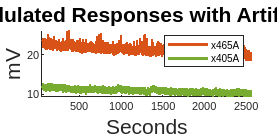

%% Test plot for new time range
figure ('Position',[100, 100, 800, 400])
hold on;
p1 = plot(time, data.streams.(GCAMP).data,'color',GCAMP_color,'LineWidth',2); hold on; 
p2 = plot(time, data.streams.(ISOS).data,'color',ISOS_color,'LineWidth',2);
title('Raw Demodulated Responses with Artifact Removed','fontsize',16);
xlabel('Seconds','fontsize',16)
ylabel('mV','fontsize',16);
axis tight;
legend([p1 p2], {GCAMP, ISOS});

% Setting up chow timestamps
% Timestamp refers to the moment the pellet is removed from the feeder

data.epocs.(REF_EPOCH).onset = data.epocs.Note.onset;

data.epocs.(REF_EPOCH).offset = data.epocs.(REF_EPOCH).onset + .1;
data.epocs.(REF_EPOCH).name = REF_EPOCH; 

data.epocs.(REF_EPOCH).data = ones(1, length(data.epocs.(REF_EPOCH).onset));



%%%% Using tdtfilter to snip data %%%%
data = TDTfilter(data, REF_CHANNEL, 'TIME', time_range);

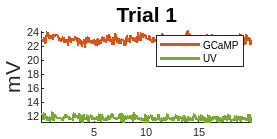

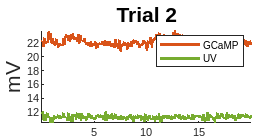

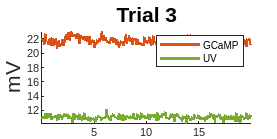

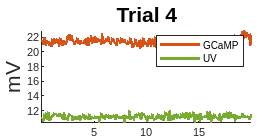

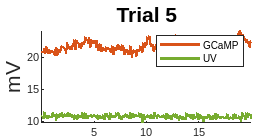

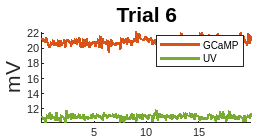

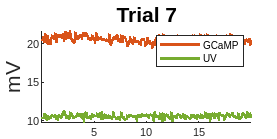

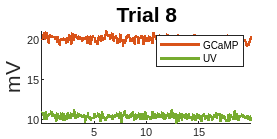

% Plotting filtered data
time2 = (1:length(data.streams.(GCAMP).filtered{1}))/data.streams.(GCAMP).fs;

for ii = 1:length(data.streams.(GCAMP).filtered)
    % Plot both unprocessed demodulated data streams
    figure('Position',[100, 100, 800, 400])
    hold on; 
    p1 = plot(time2, data.streams.(GCAMP).filtered{ii},'color',GCAMP_color,'LineWidth',2);
    p2 = plot(time2, data.streams.(ISOS).filtered{ii},'color',ISOS_color,'LineWidth',2);
    title(sprintf('Trial %d', ii),'fontsize',16);
    ylabel('mV','fontsize',16);
    axis tight;
    legend([p1 p2], {'GCaMP','UV'});
end

minLength2 = min(cellfun('prodofsize', data.streams.(ISOS).filtered));
minLength1 = min(cellfun('prodofsize', data.streams.(GCAMP).filtered));

data.streams.(ISOS).filtered = cellfun(@(x) x(1:minLength2), ...
    data.streams.(ISOS).filtered, ...
    'UniformOutput',false);
data.streams.(GCAMP).filtered = cellfun(@(x) x(1:minLength1), ...
    data.streams.(GCAMP).filtered, ...
    'UniformOutput',false);

% Downsampling and averaging ISOS
allSignals = cell2mat(data.streams.(ISOS).filtered');
ISOS_ds = zeros(size(allSignals(:,1:N:end-N+1)));
for ii = 1:size(allSignals, 1)
    ISOS_ds(ii,:) = arrayfun( ...
        @(i) mean(allSignals(ii, i:i+N-1)), ...
        1:N:length(allSignals)-N+1 ...
    );
end
minLength_ISOS = size(ISOS_ds, 2)

minLength_ISOS = 40


meanSignal_ISOS = mean(ISOS_ds);
stdSignal_ISOS = std(double(ISOS_ds))/sqrt(size(ISOS_ds,1));
dcSignal_ISOS = mean(meanSignal_ISOS);

% Downsampling and averaging GCAMP
allSignals = cell2mat(data.streams.(GCAMP).filtered');
GCAMP_ds = zeros(size(allSignals(:,1:N:end-N+1)));
for ii = 1:size(allSignals, 1)
    GCAMP_ds(ii,:) = arrayfun( ...
        @(i) mean(allSignals(ii, i:i+N-1)), ...
        1:N:length(allSignals)-N+1 ...
    );
end
minLength_GCAMP = size(GCAMP_ds, 2)

minLength_GCAMP = 40


meanSignal_GCAMP = mean(GCAMP_ds);
stdSignal_GCAMP = std(double(GCAMP_ds))/sqrt(size(GCAMP_ds,1));
dcSignal_GCAMP = mean(meanSignal_GCAMP);

## **Plot Epoch Averaged Response**

fsISOS = data.streams.(ISOS).fs

fsISOS = 1.0173e+03

% Time vectors
tsISOS = time_range(1) + (1:minLength_ISOS) / data.streams.(ISOS).fs*N

tsISOS =    -9.5085   -9.0170   -8.5254   -8.0339   -7.5424   -7.0509   -6.5594   -6.0678   -5.5763   -5.0848   -4.5933   -4.1018   -3.6102   -3.1187   -2.6272   -2.1357   -1.6442   -1.1526   -0.6611   -0.1696    0.3219    0.8134    1.3050    1.7965    2.2880    2.7795    3.2710    3.7626    4.2541    4.7456    5.2371    5.7286    6.2202    6.7117    7.2032    7.6947    8.1862    8.6778    9.1693    9.6608


tsGCAMP = time_range(1) + (1:minLength_GCAMP) / data.streams.(GCAMP).fs*N

tsGCAMP =    -9.5085   -9.0170   -8.5254   -8.0339   -7.5424   -7.0509   -6.5594   -6.0678   -5.5763   -5.0848   -4.5933   -4.1018   -3.6102   -3.1187   -2.6272   -2.1357   -1.6442   -1.1526   -0.6611   -0.1696    0.3219    0.8134    1.3050    1.7965    2.2880    2.7795    3.2710    3.7626    4.2541    4.7456    5.2371    5.7286    6.2202    6.7117    7.2032    7.6947    8.1862    8.6778    9.1693    9.6608



% DC Offset
meanSignal_ISOS = meanSignal_ISOS - dcSignal_ISOS;
meanSignal_GCAMP = meanSignal_GCAMP - dcSignal_GCAMP;

% Plot
figure;
subplot(4, 1, 1)
p1 = plot(tsISOS, meanSignal_ISOS, 'Color',ISOS_color,'LineWidth',3); hold on;
p2 = plot(tsGCAMP, meanSignal_GCAMP, 'Color',GCAMP_color,'LineWidth',3);

onsetLine = line([0 0], [min(GCAMP_ds(:) - dcSignal_GCAMP), ...
    max(GCAMP_ds(:)) - dcSignal_GCAMP], ...
    'Color', gray1, 'LineStyle','-', 'LineWidth', 3 ...
)

onsetLine =   Line with properties:

              Color: [0.7000 0.7000 0.7000]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0]
              YData: [-1.7735 2.5202]
              ZData: [1×0 double]

  Show all properties


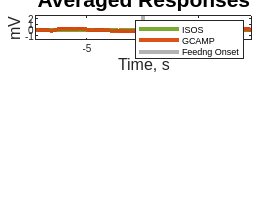


title('Averaged Responses', 'fontsize', 16);
ylabel('mV', 'fontsize', 16);
axis tight;
legend([p1, p2, onsetLine], {'ISOS', 'GCAMP', 'Feedng Onset'}, 'AutoUpdate', 'off');
xlabel('Time, s','FontSize',12)
ylabel('mV', 'FontSize', 12)

% ISOS std error bands
xx_ISOS = [tsISOS, fliplr(tsISOS)];
yy_ISOS = [meanSignal_ISOS + stdSignal_ISOS, fliplr(meanSignal_ISOS - stdSignal_ISOS)];
h_ISOS = fill(xx_ISOS, yy_ISOS, 'g');
set(h_ISOS, 'FaceAlpha',.25, 'EdgeColor','none')

% GCAMP std error bands
xx_GCAMP = [tsGCAMP, fliplr(tsGCAMP)];
yy_GCAMP = [meanSignal_GCAMP + stdSignal_GCAMP, fliplr(meanSignal_GCAMP - stdSignal_GCAMP)];
h_GCAMP = fill(xx_GCAMP, yy_GCAMP, 'r');
set(h_GCAMP, 'facealpha',.25,'edgecolor','none')

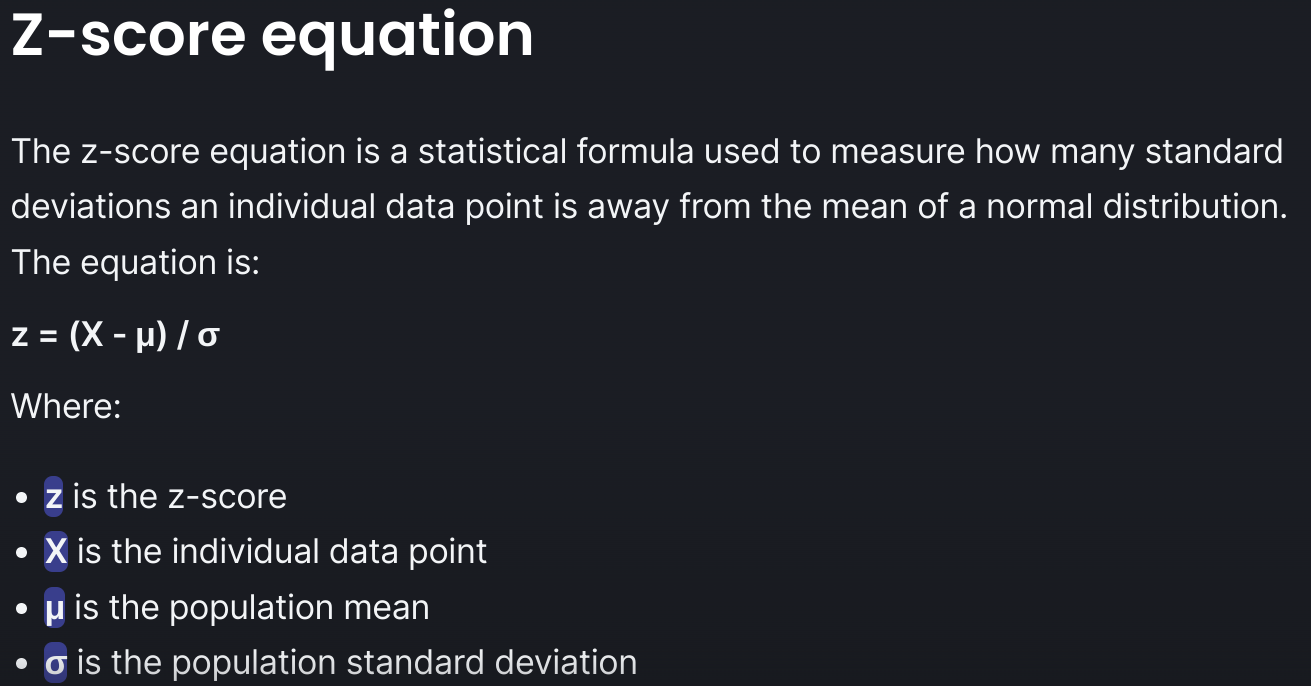

% figure;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Heat Map based on z score of GCAMP fit subtracted ISOS

% Fitting 405 channel onto 465 channel to detrend signal bleaching
% Scale and fit data
% Algorithm sourced from Tom Davidson's Github:
% https://github.com/tjd2002/tjd-shared-code/blob/master/matlab/photometry/FP_normalize.m

bls = polyfit(ISOS_ds(1:end), GCAMP_ds(1:end), 1);
Y_fit_all = bls(1) .* ISOS_ds + bls(2);
Y_dF_all = GCAMP_ds - Y_fit_all;

% Getting z-scores
zall = zeros(size(Y_fit_all));
for i = 1:size(Y_dF_all, 1)
    BASELINE = tsGCAMP(1,:) < baseline_per(2) & tsGCAMP(1,:) > baseline_per(1);
    BL__mean = mean(Y_dF_all(i,BASELINE));
    BL_std = std(Y_dF_all(i,BASELINE));
    zall(i,:) = (Y_dF_all(i,:) - BL__mean)/BL_std; % Z score per bin
end


Standard Error formula

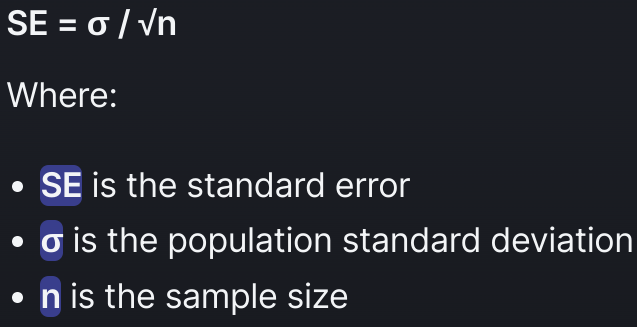

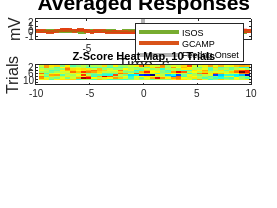

% Standard error of the z-score
zStdError = std(zall)/sqrt(size(zall,1));

% Heat map

subplot(4,1,2)

imagesc(tsGCAMP, 1, zall);
colormap('jet'); % c1 = colorbar;
title(sprintf( ...
    'Z-Score Heat Map, %d Trials', ...
    numel(data.streams.(ISOS).filtered) ...
));
ylabel('Trials', 'FontSize', 12);

xlim([-10.0 10.0])
ylim([0.5 13.5])

Mean z-score and its standard error band

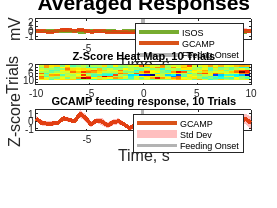

% figure;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Scale and plot band values for 2nd subplot
zGCAMP_XX = [tsGCAMP, fliplr(tsGCAMP)];
zGCAMP_YY = [mean(zall)-zStdError, fliplr(mean(zall)+zStdError)];


subplot(4,1,3)
plot(tsGCAMP, mean(zall), ...
    'color',GCAMP_color, ...
    'LineWidth', 3 ...
); hold on;

h = fill(zGCAMP_XX, zGCAMP_YY, 'r');
set(h, 'facealpha',.25,'edgecolor','none')

line([0 0], ...
    [min(zGCAMP_YY), max(zGCAMP_YY)], ...
    'Color', gray1, ...
    'LineWidth', 2)

% Finish up the plot
axis tight
xlabel('Time, s','FontSize',12)
ylabel('Z-score', 'FontSize', 12)
legend('GCAMP', 'Std Dev', 'Feeding Onset')
title(sprintf('GCAMP feeding response, %d Trials', ...
    numel(data.streams.(ISOS).filtered) ...
))

Area under the curve and two-sample T-Test comparisons for baseline vs feeding 

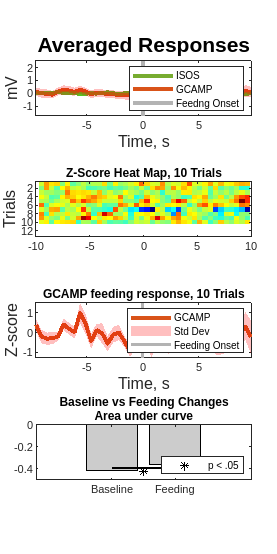

% figure;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Quantify changes as area under the curve 
% for cue (-5 sec) and shock (0 sec)
AUC=[]; % cue, shock
AUC(1,1)=trapz(mean( ...
    zall(:,tsGCAMP(1,:) < -3 & tsGCAMP(1,:) > -5) ...
));
AUC(1,2)=trapz(mean( ...
    zall(:,tsGCAMP(1,:) > 0 & tsGCAMP(1,:) < 2) ...
));
subplot(4,1,4);
hBar = bar(AUC, 'FaceColor', [.8 .8 .8]);

% Run a two-sample T-Test
[h,p,ci,stats] = ttest2( ...
    mean(zall(:,tsGCAMP(1,:) < -3 & tsGCAMP(1,:) > -5)), ...
    mean(zall(:,tsGCAMP(1,:) > 0 & tsGCAMP(1,:) < 2)) ...
);

% Plot significance bar if p < .05
hold on;
centers = get(hBar, 'XData');
plot(centers(1:2), ...
    [1 1]*AUC(1,2)*1.1, ...
    '-k', ...
    'LineWidth',2 ...
)
p1 = plot(mean(centers(1:2)), AUC(1,2)*1.2, '*k');
set(gca,'xticklabel',{'Baseline','Feeding'});
title({'Baseline vs Feeding Changes', ...
    'Area under curve'} ...
)
legend(p1, 'p < .05','Location','southeast');

set(gcf, 'Position',[100, 100, 500, 1000])